close all;
clear variables;

breath = importdata("data\breath.txt");
breathRaw = breath.data;

air = importdata("data\air.txt");
airRaw = air.data;

tt = importdata("data\TotalTime.txt");
tt = tt.data;

fr = importdata("data\samplingFrequency.txt");
fr = fr.data;

T = importdata("data\temperature.txt");
T = T.data + 273;

w = importdata("data\volumeFractionWater.txt");
w = w.data;

%Нормировка

windowSize = 5;
b = (1/windowSize) * ones(1, windowSize);
a = 1;

airFiltered = filter(b, a, airRaw());
breathFiltered = filter(b, a, breathRaw());

start = 30;

airFiltered = airFiltered(start:end, :);
breathFiltered = breathFiltered(start:end, :);
fr = 1/fr;
time = (0:fr:tt)';
time = time(start:end);

cAir = polyfit(time, airFiltered(:, 1), 3);
cBreath = polyfit(time, breathFiltered(:, 1), 3);

air = airFiltered - polyval(cAir, time);
airNorm = air ./ max(air);

breath = breathFiltered - polyval(cBreath, time);
breathNorm = breath ./ max(breath);

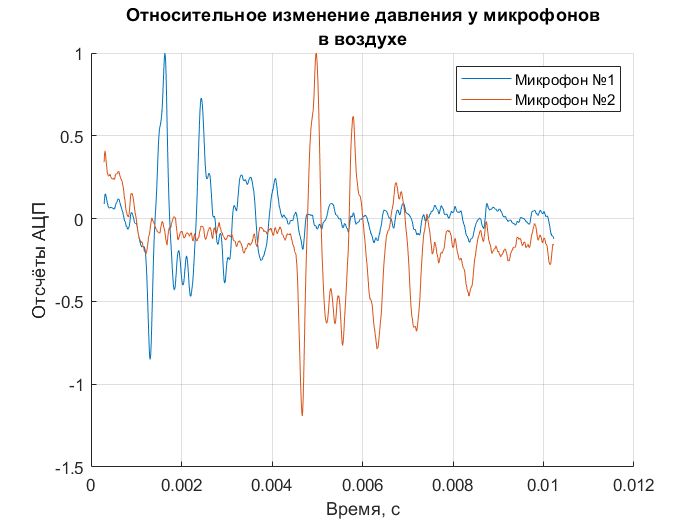

% air

zNames = {'Микрофон №1'; 'Микрофон №2'};

airF = figure();
hold on;

for i = 1:2
    plot(time, airNorm(:, i), 'DisplayName', zNames{i});
end

grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе'});
xlabel('Время, с');
ylabel('Отсчёты АЦП');

legend('Location', 'NorthEast');
saveas(airF, "graph_air.png");  %изменена ссылка

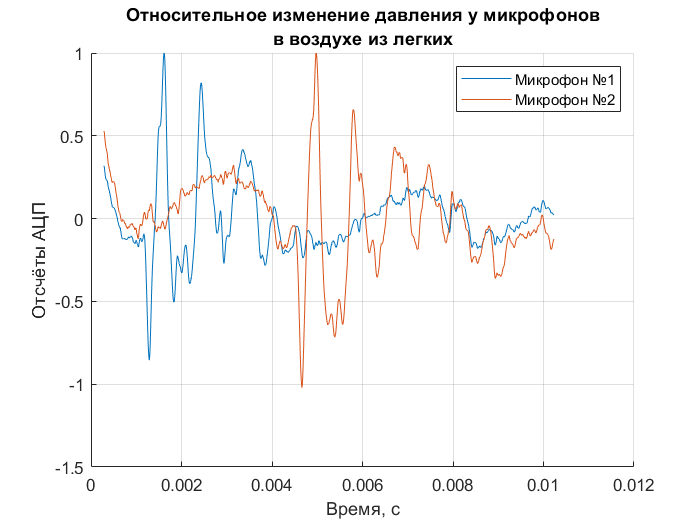

% breath

zNames = {'Микрофон №1'; 'Микрофон №2'};

breathF = figure();
hold on;

for i = 1:2
    plot(time, breathNorm(:, i), 'DisplayName', zNames{i});
end

grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе из легких'});
xlabel('Время, с');
ylabel('Отсчёты АЦП');

legend('Location', 'NorthEast');
saveas(breathF, "graph_breath.png");  %изменена ссылка

% experimental speed without CO2

P = airNorm(1, 1);
T1 = time(1);
for i = 2:length(airNorm)
    if airNorm(i, 1)>P
        P = airNorm(i, 1);
        T1 = time(i);
    end
end

P = airNorm(1, 2);
T2 = time(1);
for i = 2:length(airNorm)
    if airNorm(i, 2)>P
        P = airNorm(i, 2);
        T2 = time(i);
    end
end

TimeWithoutCO2_max = T2 -T1;

P = airNorm(1, 1);
T1 = time(1);
for i = 2:length(airNorm)
    if airNorm(i, 1)<P
        P = airNorm(i, 1);
        T1 = time(i);
    end
end

P = airNorm(1, 2);
T2 = time(1);
for i = 2:length(airNorm)
    if airNorm(i, 2)<P
        P = airNorm(i, 2);
        T2 = time(i);
    end
end

TimeWithoutCO2_min = T2 -T1;

speedWithoutCO2 = (2*1.158)/(TimeWithoutCO2_max + TimeWithoutCO2_min);  % расстояние / среднее время между пиками [м/с]

% experimental speed with CO2

P = breathNorm(1, 1);
T1 = time(1);
for i = 2:length(breathNorm)
    if breathNorm(i, 1)>P
        P = breathNorm(i, 1);
        T1 = time(i);
    end
end

P = breathNorm(1, 2);
T2 = time(1);
for i = 2:length(breathNorm)
    if breathNorm(i, 2)>P
        P = breathNorm(i, 2);
        T2 = time(i);
    end
end

TimeWithCO2_max = T2 -T1;

P = breathNorm(1, 1);
T1 = time(1);
for i = 2:length(breathNorm)
    if breathNorm(i, 1)<P
        P = breathNorm(i, 1);
        T1 = time(i);
    end
end

P = breathNorm(1, 2);
T2 = time(1);
for i = 2:length(breathNorm)
    if breathNorm(i, 2)<P
        P = breathNorm(i, 2);
        T2 = time(i);
    end
end

TimeWithCO2_min = T2 -T1;

speedWithCO2 = (2*1.158)/(TimeWithCO2_max + TimeWithCO2_min);  % расстояние / среднее время между пиками [м/с]

% рассчёт концентрации Н2О

CP = [1.0036; 1.863; 0.838];  % вносим константы
CN = [0.7166; 1.403; 0.649];
m = [28.97; 18.01; 44.01];
T = 295.4;
R = 8314;

k = 0;
X = [1-0.0003-k/1000; k/1000; 0.0003];

sum_CP = 0;
sum_CN = 0;
sum_m = 0;
for i = 1:3
    sum_CP = sum_CP + (m(i)*CP(i)*X(i));
    sum_CN = sum_CN + (m(i)*CN(i)*X(i));
    sum_m = sum_m + (m(i)*X(i));
end
g = sum_CP/sum_CN;
U = sqrt((g*R*T)/sum_m);

while U<speedWithoutCO2
    k = k+1;
    X = [1-0.0003-k/1000; k/1000; 0.0003];

    sum_CP = 0;
    sum_CN = 0;
    sum_m = 0;
    for i = 1:3
        sum_CP = sum_CP + (m(i)*CP(i)*X(i));
        sum_CN = sum_CN + (m(i)*CN(i)*X(i));
        sum_m = sum_m + (m(i)*X(i));
    end
    g = sum_CP/sum_CN;
    U = sqrt((g*R*T)/sum_m);
end

%теоретический расчет скорости звука в воздухе

w = X;
m = [28.97, 18.01, 44.01];
Cp = [1.0036, 1.863, 0.838];
Cv = [0.7166, 1.403, 0.649];

Cv_0 = 0;
for i = 1:3
    Cv_0 = Cv_0 + m(i) * Cv(i) * w(i);
end

Cp_0 = 0;
for i = 1:3
    Cp_0 = Cp_0 + m(i) * Cp(i) * w(i);
end

m_0 = 0;
for i = 1:3
    m_0 = m_0 + m(i) * w(i);
end

R = 8.314 %дж/моль*К

R = 8.3140

u1 = sqrt((Cp_0 * R * T)/(Cv_0 * m_0 / 1000));
u1 %м/с

u1 = 345.1922

% зависимость скорости звука от концентрации CO2
w_CO2 = linspace(0, 0.03, 50);

u = zeros(1, 50);

for k = 1:50
    Cv_0 = 0;
    for i = 1:2
        Cv_0 = Cv_0 + m(i) * Cv(i) * w(i);
    end
    Cv_0 = Cv_0 + m(i) * Cv(i) * w_CO2(k);

    Cp_0 = 0;
    for i = 1:2
        Cp_0 = Cp_0 + m(i) * Cp(i) * w(i);
    end
     Cp_0 = Cp_0 + m(i) * Cp(i) * w_CO2(k);

    m_0 = 0;
    for i = 1:2
        m_0 = m_0 + m(i) * w(i)
    end
    m_0 = m_0 + m(i) * w_CO2(k);
    u(k) = sqrt((Cp_0 * R * T)/(Cv_0 * m_0 / 1000))
end

m_0 = 28.6137

m_0 = 28.8298

u =   345.2767         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953         0         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244         0         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537         0         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830         0         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123         0         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123  342.3417         0         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123  342.3417  342.2711         0         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123  342.3417  342.2711  342.2006         0         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123  342.3417  342.2711  342.2006  342.1301         0         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123  342.3417  342.2711  342.2006  342.1301  342.0597         0         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123  342.3417  342.2711  342.2006  342.1301  342.0597  341.9893         0         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123  342.3417  342.2711  342.2006  342.1301  342.0597  341.9893  341.9190         0         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123  342.3417  342.2711  342.2006  342.1301  342.0597  341.9893  341.9190  341.8487         0


m_0 = 28.6137

m_0 = 28.8298

u =   345.2767  345.2041  345.1316  345.0591  344.9867  344.9144  344.8420  344.7698  344.6975  344.6254  344.5533  344.4812  344.4092  344.3372  344.2653  344.1934  344.1216  344.0498  343.9781  343.9064  343.8347  343.7632  343.6916  343.6202  343.5487  343.4773  343.4060  343.3347  343.2635  343.1923  343.1211  343.0500  342.9790  342.9080  342.8370  342.7661  342.6953  342.6244  342.5537  342.4830  342.4123  342.3417  342.2711  342.2006  342.1301  342.0597  341.9893  341.9190  341.8487  341.7784


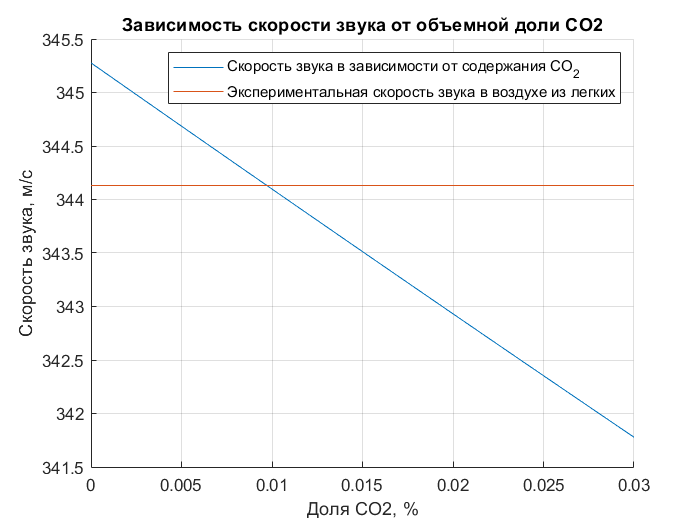

% график
lineF = figure();
hold on;

plot(w_CO2(1, :), u(1, :));
u_exp = ones(1, 50)*speedWithCO2;
plot(w_CO2(1, :), u_exp(1, :));


grid on;
title({'Зависимость скорости звука от объемной доли CO2'});
xlabel('Доля CO2, %');
ylabel('Скорость звука, м/с');

legend('Скорость звука в зависимости от содержания CO_2', 'Экспериментальная скорость звука в воздухе из легких', 'Location', 'NorthEast');
saveas(lineF, "result.png");